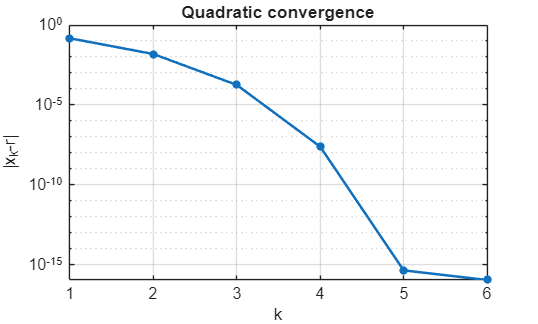

clc; clear; close all

%question 1
%xe^x − 2 = 0 near x = 1 
f=@(x) x.*exp(x)-2;
df=@(x) exp(x).*(x+1);

%using the fzero we will find the real roots near x=1
%Displays 15 decimal digits
format long e;
r=fzero(f,1); 
x=zeros(6,1);
x(1)=1;
%using the newton method 

%x is a single value which is updated again and again
x=1;
%we are iterating for 6time assume an number for iteration unless its given
for k=1:5
    x(k+1) = x(k) - f(x(k)) / df(x(k)); % Update x using Newton's method
end

%Displays 4 decimal digits
format short e;
err = x - r;

%its a plotting function 
semilogy(abs(err),'.-',MarkerSize=15,LineWidth=1.5)
xlabel('k'), ylabel('|x_k-r|')
title('Quadratic convergence')
grid on;